clc;clear
%处理各省数据
namelist = dir('*k.xls');
disp("开始导入各省数据");

开始导入各省数据


provincialData = cell(1,length(namelist));
for i = 1:length(namelist)
    provincialData{1,i} = xlsread(namelist(i).name);%读取excel 文件
end
provincialData=provincialData';
for i=1:length(namelist)
    temp=strsplit(namelist(i).name,'k');
    provincialList(i)=temp(1);
end
disp("导入完成");

导入完成


for i=1:length(provincialData)
    provincial=provincialData{i};
    %铁（公）路总长 人均民用（私人）汽车拥有量 高速公路占比 运输路线每公里年货均（客）运量 邮政平均每一营业网点
    allData{i}=[provincial(:,[1 3]) provincial(:,[19 20])./provincial(:,18) provincial(:,4)./provincial(:,3) provincial(:,[13 14])./((provincial(:,1)+provincial(:,3)).*(1e9)) provincial(:,17) provincial(:,[6 7 8])./provincial(:,5) provincial(:,[10 11 12])./provincial(:,9)];%读取变量
end
VariableTable={ '铁路营业里程','公路里程' '人均私人汽车拥有量','人均民用汽车拥有量' ,'高速公路占比' ,'运输路线每公里年均货运量','运输路线每公里年均客运量' ,'邮政平均每一营业网点','铁路占总旅客周转量的百分比','公路占旅客总周转量的百分比','水路占旅客总周转量的百分比','铁路占货运总周转量的百分比','公路占货运总周转量的百分比','水路占货运总周转量的百分比'};
VariableTable=VariableTable';

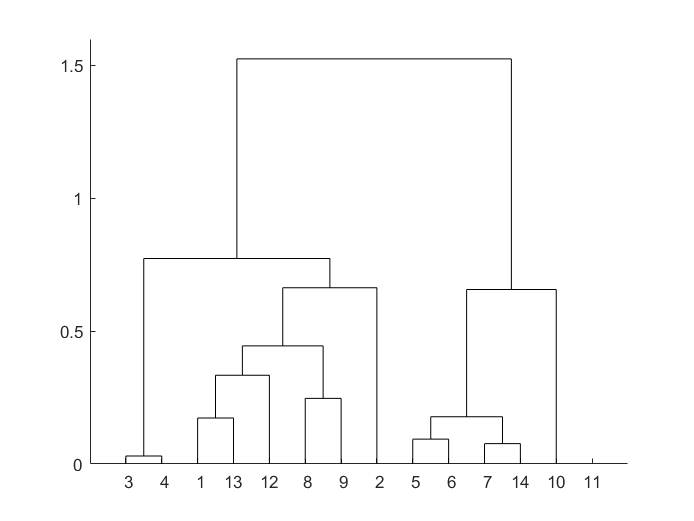

temp1=zeros(9,14);
temp2=zeros(14,14);
for year=1:length(allData)
    figure
    temp4=[];
    for i=1:length(allData)
        temp3=allData{i};
        temp4=[temp4; temp3(year,:)];%整理数据
    end
    b=zscore(temp4);
    temp1=temp1+b;
    r=corrcoef(b);
    temp2=temp2+r;
end
figure
b=temp1./length(allData);
r=temp2./length(allData); %加总计算2020-2012的相关矩阵后求均值，寻找相关性强的元素
d=pdist(b','correlation');
z=linkage(d,'average');
h=dendrogram(z);
set(h,'Color','k')

T=cluster(z,'maxclust',7);
for i=1:7
    tm=find(T==i);
    tm=reshape(tm,1,length(tm));
    temp6={};
    %设置导出内容
    for j=1:length(tm)
        temp6{j}=[int2str(tm(j)) VariableTable{tm(j)}];
    end
    fprintf("第%d类的有:",i);
    for l=1:length(temp6)
        fprintf(temp6{l}+" ")
    end
end

第1类的有:

8邮政平均每一营业网点 9铁路占总旅客周转量的百分比 

第2类的有:

1铁路营业里程 12铁路占货运总周转量的百分比 13公路占货运总周转量的百分比 

第3类的有:

10公路占旅客总周转量的百分比 

第4类的有:

5高速公路占比 6运输路线每公里年均货运量 7运输路线每公里年均客运量 14水路占货运总周转量的百分比 

第5类的有:

2公路里程 

第6类的有:

3人均私人汽车拥有量 4人均民用汽车拥有量 

第7类的有:

11水路占旅客总周转量的百分比 

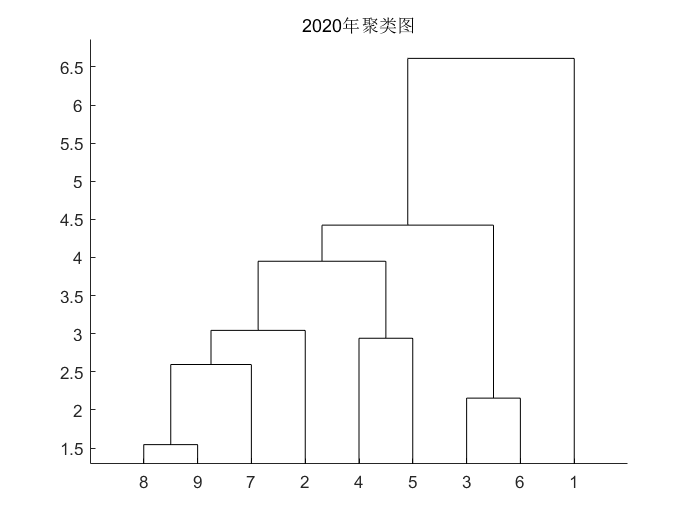

划分成3类的结果如下:


第1类的有:

山东 河北 

第2类的有:

四川 广东 广西 河南 陕西 黑龙江 

第3类的有:

上海 

*******************

划分成4类的结果如下:


第1类的有:

广东 广西 

第2类的有:

四川 河南 陕西 黑龙江 

第3类的有:

山东 河北 

第4类的有:

上海 

*******************

划分成5类的结果如下:


第1类的有:

四川 

第2类的有:

河南 陕西 黑龙江 

第3类的有:

广东 广西 

第4类的有:

山东 河北 

第5类的有:

上海 

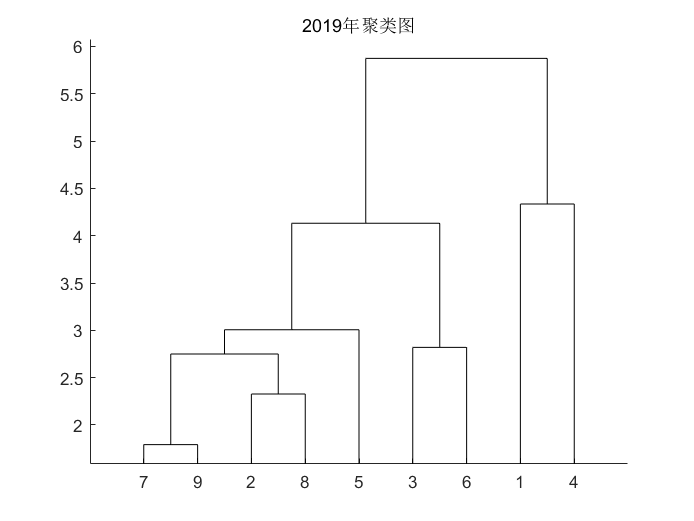

划分成3类的结果如下:


第1类的有:

上海 

第2类的有:

广东 

第3类的有:

四川 山东 广西 河北 河南 陕西 黑龙江 

*******************

划分成4类的结果如下:


第1类的有:

山东 河北 

第2类的有:

四川 广西 河南 陕西 黑龙江 

第3类的有:

上海 

第4类的有:

广东 

*******************

划分成5类的结果如下:


第1类的有:

广西 

第2类的有:

四川 河南 陕西 黑龙江 

第3类的有:

山东 河北 

第4类的有:

上海 

第5类的有:

广东 

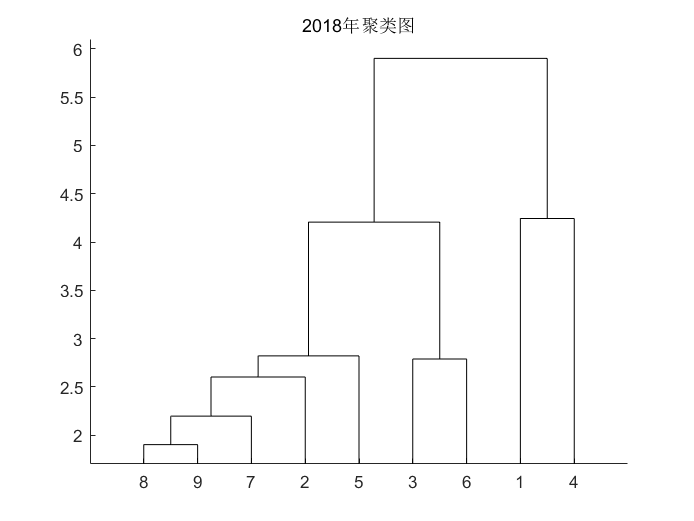

划分成3类的结果如下:


第1类的有:

上海 

第2类的有:

广东 

第3类的有:

四川 山东 广西 河北 河南 陕西 黑龙江 

*******************

划分成4类的结果如下:


第1类的有:

山东 河北 

第2类的有:

四川 广西 河南 陕西 黑龙江 

第3类的有:

上海 

第4类的有:

广东 

*******************

划分成5类的结果如下:


第1类的有:

广西 

第2类的有:

四川 河南 陕西 黑龙江 

第3类的有:

山东 河北 

第4类的有:

上海 

第5类的有:

广东 

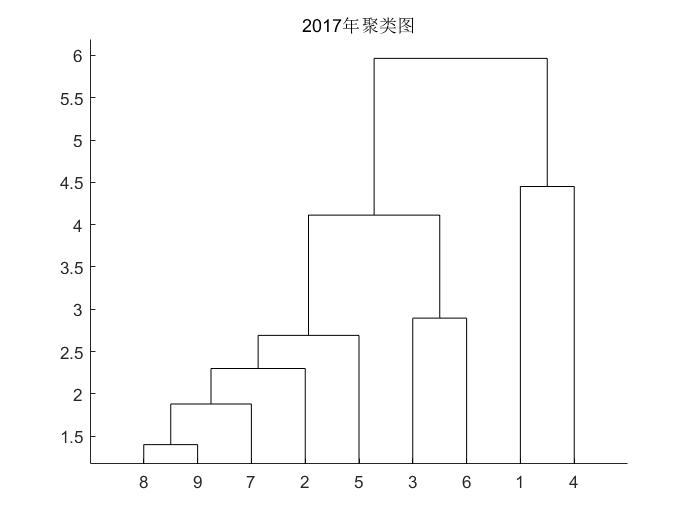

划分成3类的结果如下:


第1类的有:

上海 

第2类的有:

广东 

第3类的有:

四川 山东 广西 河北 河南 陕西 黑龙江 

*******************

划分成4类的结果如下:


第1类的有:

四川 广西 河南 陕西 黑龙江 

第2类的有:

山东 河北 

第3类的有:

上海 

第4类的有:

广东 

*******************

划分成5类的结果如下:


第1类的有:

山东 

第2类的有:

河北 

第3类的有:

四川 广西 河南 陕西 黑龙江 

第4类的有:

上海 

第5类的有:

广东 

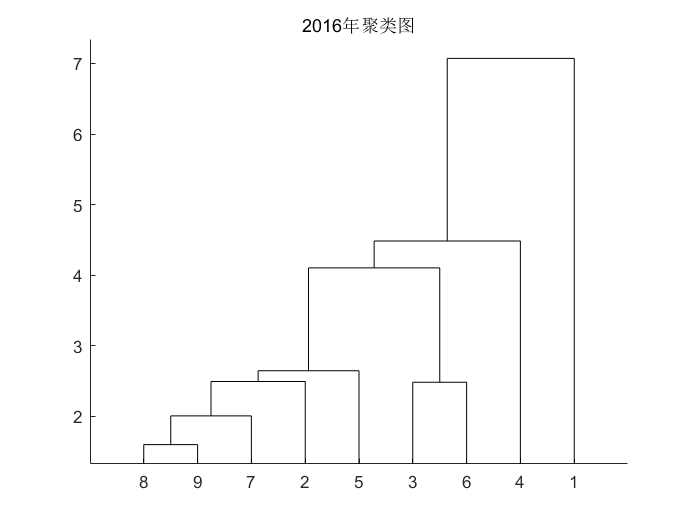

划分成3类的结果如下:


第1类的有:

广东 

第2类的有:

四川 山东 广西 河北 河南 陕西 黑龙江 

第3类的有:

上海 

*******************

划分成4类的结果如下:


第1类的有:

山东 河北 

第2类的有:

四川 广西 河南 陕西 黑龙江 

第3类的有:

广东 

第4类的有:

上海 

*******************

划分成5类的结果如下:


第1类的有:

广西 

第2类的有:

四川 河南 陕西 黑龙江 

第3类的有:

山东 河北 

第4类的有:

广东 

第5类的有:

上海 

%绘制制2016-2020 年聚类图
for year=1:5
    figure
    temp9=[];
    for i=1:length(allData)
        temp7=allData{i};
        temp9=[temp9; temp7(year,[1 3 4 5 6 7 8 9 12 13 14])];%整理数据
    end
    gj=zscore(temp9);
    y=pdist(gj);
    z=linkage(y,"average");
    %绘图
    h=dendrogram(z);
    set(h,'Color','k')
    title(int2str(2021-year)+"年聚类图");
    for k=3:5
        fprintf("划分成%d类的结果如下:\n",k)
        T=cluster(z,'maxclust',k);%划分k类
        for i=1:k
            tm=find(T==i);%求第i类的对象
            tm=reshape(tm,1,length(tm));
            temp10={};
            %设置导出内容
            for j=1:length(tm)
                temp10{j}=provincialList{tm(1,j)};
            end
            fprintf("第%d类的有:",i);
            for l=1:length(temp10)
                fprintf(temp10{l}+" ")
            end
        end
        if k==5
            break
        end
    fprintf("*******************");
    end
end